## **Przetwarzanie Sygnałów Cyfrowych**

# Analiza harmoniczna cz. 2

## Jan Rosa 410269 AiR

## Ćwiczenie 1

Transformata fouriera sygnału sin(wt)

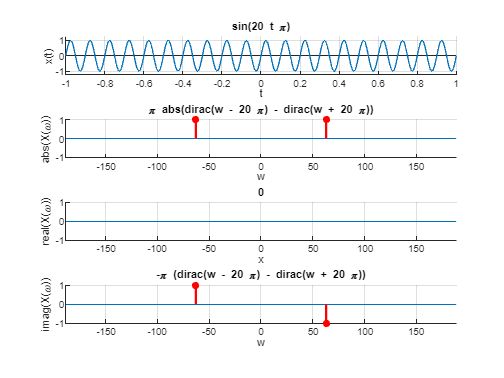

syms t
f0 = 10; %Hz
w0 = 2*pi*f0;
x = sin(w0*t);
fourT_dirac(x, f0)

## Zad 2

### a) sygnaª cos(ω0t)

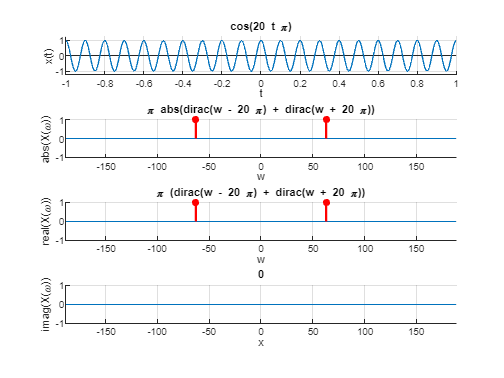

f0 = 10; %Hz
w0 = 2*pi*f0;
x = cos(w0*t);
fourT_dirac(x, f0)

### b) sygnaª staªy o warto±ci 10 (do jego zde�niowanie nale»y u»y¢ polecenia sym(10))

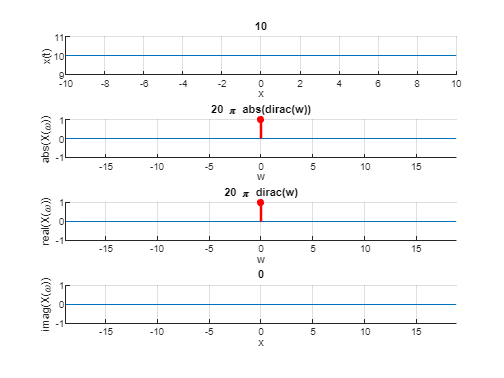

f0 = 1; %Hz
x = sym(10);
fourT_dirac(x, f0)

### c) skok jednostkowy o amplitudzie 1

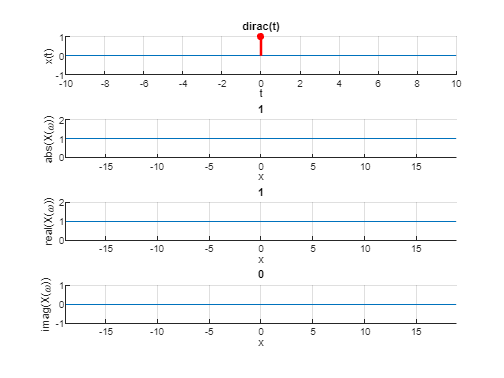

f0 = 1; %Hz
x = dirac(t);
fourT_dirac(x, f0)

### d) impuls prostok¡tny o amplitudzie 1 oraz czasie trwania Ti = 2/f0

f0 = 2;
x = rectangularPulse(-1, 1, t)

$$x = \mathrm{rectangularPulse}\left(-1,1,t\right)$$

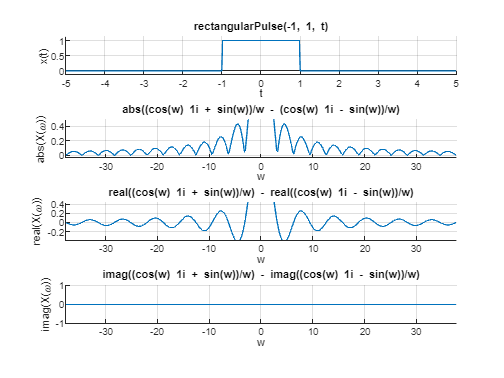

fourT_cont(x, f0)

### e) impuls trójkątny (symetryczny) o amplitudzie 1 oraz czasie trwania Ti = 2/f0 .

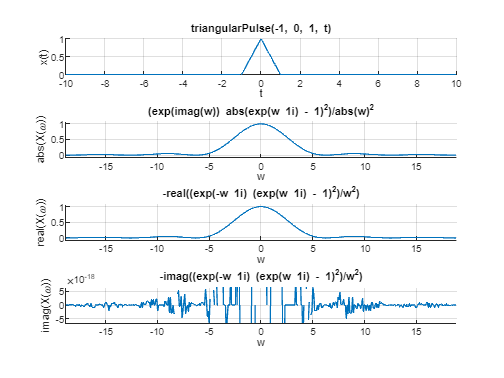

f0 = 1;
x = triangularPulse(-1/f0, 1/f0, t);
fourT_cont(x, f0)

### ZD1

Dla przebiegów cos(ω0t) oraz sin(ω0t) sporz¡d¹ równie» wykresy g¦sto±ci widmowej amplitudy oraz fazy. Porównaj je i opisz ró»nice w sprawozdaniu.

%?????????????????????????????????????????????

## Zadanie 3

Przeprowad¹ modulacj¦ sygnaªu cos(ω0t) przebiegiem sinusoidalnym o cz¦stotliwo±ci 10-krotnie mniejszej, amplitudzie 1 i gª¦boko±ci modulacji m = 0.5. Wyznacz transformat¦ Fouriera sygnaªu zmodulowanego i uzgodnij skal¦ pr¡»ków widma. Kod programu oraz wykresy samie±¢ w sprawozdaniu

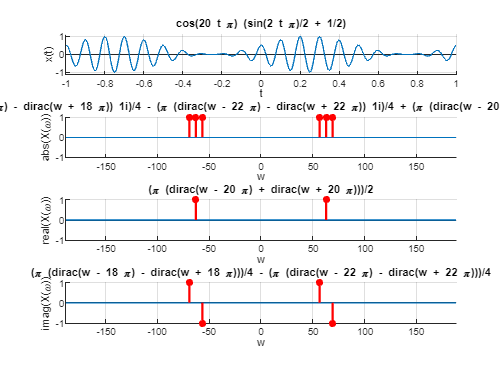

syms t
f0 = 10;
f1 = 1;
w0 = 2*pi*f0;
w1 = 2*pi*f1;
%modulacja amplitudowa
m = 0.5;
x = cos(w0*t) * ((1 - m) + m*sin(w1*t));
fourT_dirac(x, f0);

%modulacja częstotliwościowa
%x = cos(w0*t* (1 + 0.5*sin(w1*t)))
%fourT_cont(x, f0)

### ZD2

Porównaj moc sygnaªu no±nego z moc¡ wynikowego sygnaªu zmodulowanego. Napisz w sprawozdaniu jaki wpªyw na t¦ relacj¦ ma gª¦boko±¢ modulacji m. \

syms t w

xp0 = (cos(w0*t))^2;
xp = x^2;

px = 1/w1 * int(xp, t, 0 , 1/f1);
px0 = 1/w1 * int(xp0, t, 0, 1/f1);

pxd = double(px)

pxd = 0.0298

px0d = double(px0)

px0d = 0.0796

## Zad 4

x = cos(w0*t+pi/2)

$$x = \cos\left(\frac{\pi }{2}+20\,\pi \,t\right)$$

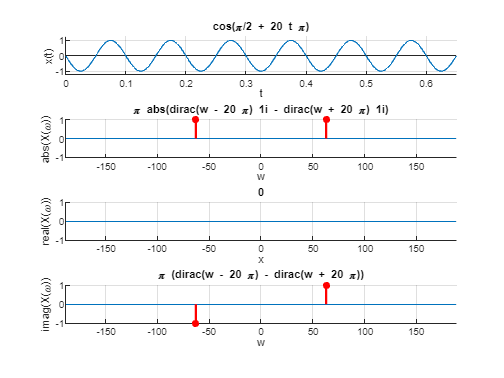

fourT_dirac_okno(x,w0/2/pi,6.5)

## Zad 5

function [] = fourT_dirac(x, f0)

syms w t

w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);

%plot signal
figure
subplot(4,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot abs of fourier
subplot(4,1,2); ylabel('abs(X(\omega))'); hold on
ezplot(abs(X_FT), BND_w); hold on; grid on
v_num = subs(abs(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot real of fourier
subplot(4,1,3); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot imag of fourier
subplot(4,1,4); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end


function [] = fourT_dirac_okno(x, f0, n_okres)

syms w t

w0 = 2*pi*f0;
BND_t = [0;n_okres/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);

%plot signal
figure
subplot(4,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot abs of fourier
subplot(4,1,2); ylabel('abs(X(\omega))'); hold on
ezplot(abs(X_FT), BND_w); hold on; grid on
v_num = subs(abs(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot real of fourier
subplot(4,1,3); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

%plot imag of fourier
subplot(4,1,4); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

function [] = fourT_cont(x, f0)

syms w t

w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2)];
X_FT = fourier(x);



%plot signal
figure
subplot(4,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);




%plot abs of fourier
subplot(4,1,2); ylabel('abs(X(\omega))'); hold on
ezplot(abs(X_FT), BND_w); hold on; grid on
%v_num = subs(abs(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


%plot real of fourier
subplot(4,1,3); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


%plot imag of fourier
subplot(4,1,4); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end


